# 问题：估计体脂率

体脂估计：此示例说明函数拟合神经网络如何基于解剖学测量值来估计体脂率。 % 在此示例中，我们尝试构建一个神经网络，该网络可以估计通过 13 个身体属性进行描述的人的体脂率： 年龄（岁），重量（磅），身高（英寸），颈围 (cm)，胸围 (cm) 腹围 (cm)，臀围 (cm)，大腿围 (cm)，膝围 (cm)，踝围 (cm) 上臂（伸展）围 (cm)，前臂围 (cm)，腕围 (cm) 这是输入与相关目标输出匹配的拟合问题的示例，我们希望所创建的神经网络不仅可以根据已知输入估计已知目标，还能泛化成针对未被用于设计解决方案的输入准确估计输出。 为什么使用神经网络？ 神经网络非常擅长处理函数拟合问题。具有足够元素（称为神经元）的神经网络可以以任意准确度拟合任何数据。它们特别适合处理非线性问题。鉴于真实情况（如体脂增加）的非线性特性，神经网络是处理此问题的优选方案。 十三个身体属性将作为神经网络的输入，体脂率将成为目标。 该网络将设计为使用体脂率已知的人体的解剖学数据进行训练以生成目标估值。 参见：https://ww2.mathworks.cn/help/deeplearning/ug/body-fat-estimation.html

## 准备数据

通过将数据组织成两个矩阵（输入矩阵 X 和目标矩阵 T）来为神经网络设置函数拟合问题的数据。 输入矩阵的每个第 i 列都将有十三个元素，表示一个体脂率已知的人体。 目标矩阵的每个对应列都将有一个元素，表示体脂率。 使用以下命令加载一个这样的数据集。

[X,T] = bodyfat_dataset;
% 我们可以查看输入 X 和目标 T 的大小。
% 请注意，X 和 T 都有 252 列。这表示 252 个体型（输入）和相关体脂率（目标）。
% 输入矩阵 X 有十三行，表示十三个属性。目标矩阵 T 只有一行，因为每个示例只需要一个输出，即体脂率。
size(X)  % ans =    13   252

ans =     13   252


size(T)  % ans =     1   252

ans =      1   252


## 设定网络结构，以便使用神经网络拟合函数

下一步是创建一个学习估计体脂率的神经网络。 由于神经网络以随机初始权重开始，因此该示例的结果在每次运行时都会略有不同。我们设置了随机种子来避免这种随机性。但这对于您自己的应用情形并不是必需的。

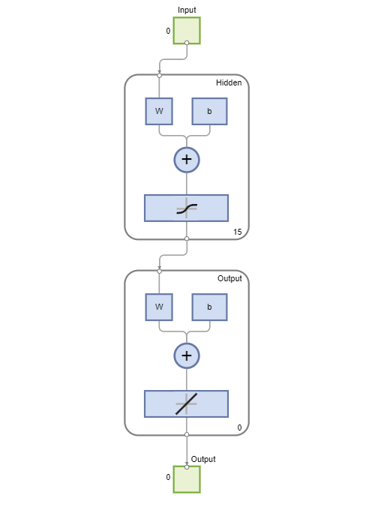

setdemorandstream(491218382)
% 双层（即，一个隐藏层）前馈神经网络可以拟合任何输入-输出关系，前提是隐藏层中有足够的神经元。非输出层称为隐含层。
% 对于此示例，我们将尝试具有 15 个神经元的单隐藏层。一般情况下，问题越困难，需要的神经元和层就越多。问题越简单，需要的神经元就越少。
% 输入和输出的大小为 0，因为网络尚未配置成与我们的输入数据和目标数据相匹配。这将在训练网络时进行。
net = fitnet(15);
view(net)

## 训练网络

现在网络已准备就绪，可以开始训练。样本自动分为训练集、验证集和测试集。训练集用于对网络进行训练。只要网络针对验证集持续改进，训练就会继续。测试集提供完全独立的网络准确度测量。 神经网络训练工具显示正在接受训练的网络和用于训练该网络的算法。它还显示训练过程中的训练状态以及停止训练的条件（以绿色突出显示）。 底部的按钮用于打开有用的绘图，这些图可以在训练期间和训练后打开。算法名称和绘图按钮旁边的链接可打开有关这些主题的文档。

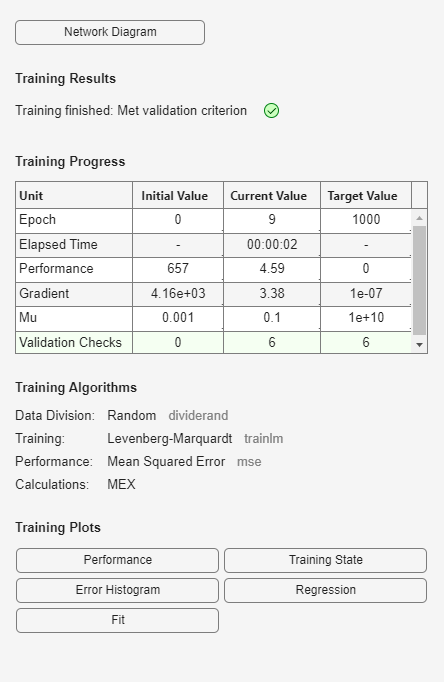

[net,tr] = train(net,X,T);

nntraintool

Unrecognized function or variable 'nntraintool'.

nntraintool('close')

% 要查看在训练过程中网络性能的改善情况，请点击训练工具中的 Performance 按钮，或调用 PLOTPERFORM。
% 性能以均方误差衡量，并以对数刻度显示。随着网络训练的加深，均方误差迅速降低。
% 绘图会显示训练集、验证集和测试集的性能。最终网络是针对验证集性能最好的网络。
plotperform(tr)

## 测试神经网络

现在可以相对于测试样本测量经过训练的神经网络的均方误差。这将使我们能够了解网络在应用于真实数据时表现如何。

testX = X(:,tr.testInd);
testT = T(:,tr.testInd);
testY = net(testX);
perf = mse(net,testT,testY)  % perf =   36.9404

% 衡量神经网络数据拟合程度的另一个方法是回归图。下面绘制了所有样本的回归图。
% 回归图显示了根据相关目标值绘制的实际网络输出。如果网络已学会很好地拟合数据，
% 则此输出-目标关系的线性拟合线与图边界的交点应该在左下角和右上角附近。
% 如果不是这样，则建议进一步进行训练，或训练具有更多隐藏神经元的网络。
Y = net(X);
plotregression(T,Y)

% 衡量神经网络数据拟合程度的第三个方法是误差直方图。
% 该图可显示误差大小的分布方式。通常，大多数误差接近于零，很少有误差大幅偏离。
e = T - Y;
ploterrhist(e)

% 此示例说明了如何设计一个通过身体特征来估计体脂率的神经网络。